# Tally  votes and explore the classifications and scores .

% read in table and format it to our liking.

clsTab=jellyfish.readClassification.import_classification_file_CJF('140721');
%head(clsTab,5)
clsTab=jellyfish.readClassification.format_classification_table_CJF(clsTab);
%head(clsTab,5)
%clsTab=jellyfish.readClassification.simulationMask(clsTab,'TNG50');

Classification info based on data downloaded on 14/7/21

review and training set objecs classifications are removed. 

The raw classification data is reformatted into a new table with columns contiaing the snapshot, id  Id for the object as well as the label (jelly or not):

%Classification data is reformatted into the following table (each line is a single classification instance):
%disp(clsTab(1:5,:))



% number of Inspectors
%Inspectors=unique(clsTab.user_name);
%Inspectors=Inspectors.replace("-","_")

% number of objects
[idList, ia,ic]=unique(clsTab.subject_ids);

ngal=length(idList);



% create object table
objectTable=jellyfish.readClassification.build_object_table(clsTab);

% table(idList,clsTab.simName(ia),clsTab.snap(ia),clsTab.subfind(ia),zeros(size(idList)),zeros(size(idList)),...
%     'variableNames',{'subject_ids','sim','snap','subfind','Ncls','Ycls'});

A table of objects is generated containing identifying information. To this we will add a classficiation column in the future:

disp(objectTable(1:5,:))

    subject_ids      sim      snap    subfind    Ncls    Ycls
    ___________    _______    ____    _______    ____    ____

    5.7253e+07     "TNG50"     33        1        20      1  
    5.7253e+07     "TNG50"     33        4        20      3  
    5.7253e+07     "TNG50"     33        2        20      0  
    5.7253e+07     "TNG50"     33        3        20      1  
    5.7253e+07     "TNG50"     33        5        20      4  



snaps=unique(objectTable.snap);
zreds=round(10.*illustris.utils.snap2redshift(snaps))./10;



## add classification column

% %loop over subject ids
% for i=1:length(idList)
%     inds=find(clsTab.subject_ids==idList(i));
%     
%     objectTable.Ncls(i)=length(inds); % total number of classifications 
%     
%     objectTable.Ycls(i)=sum(clsTab.isJelly(inds)); % number of 'yes' answers 
%     
%     
% end
% 
% disp(objectTable(1:5,:))



## plot scores

Here are the distributions for the total number of classifications and yes scores for the entire classification table, after removing the training annd review samples but before enforcing the dates.

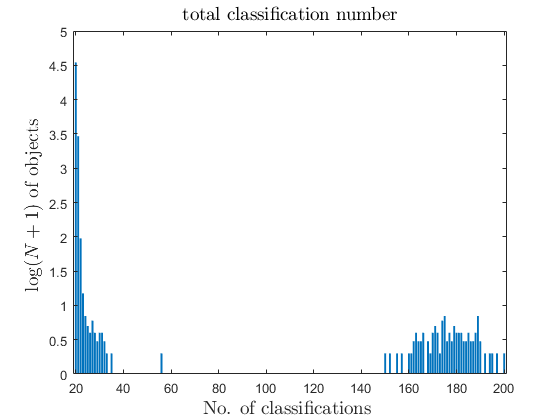

figure
xx=min(objectTable.Ncls):max(objectTable.Ncls);%  unique(objectTable.Ycls);
hs=histcounts(objectTable.Ncls,length(xx));
%histogram(objectTable.Ycls,29


 bar(xx,log10(hs+1));
% text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
%box off
%ax=gca;
%ax.YAxis.Visible='off';

%set(gca,'ytick',[])
xlabelmine('No. of classifications ');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('total classification number');


fprintf('percentage of objects with more than 20 classifications: %s',num2str(sum(objectTable.Ncls>20)./ngal.*100));

percentage of objects with more than 20 classifications: 8.3162

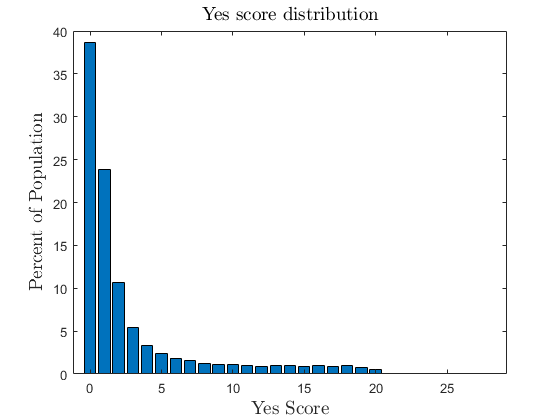



figure
hs=histcounts(objectTable.Ycls)/ngal*100;
%histogram(objectTable.Ycls,29)

 bar(0:length(hs)-1,hs);
% text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
%box off
%ax=gca;
%ax.YAxis.Visible='off';

%set(gca,'ytick',[])
xlabelmine(' Yes Score');
ylabelmine('Percent of Population');
titlemine('Yes score distribution');

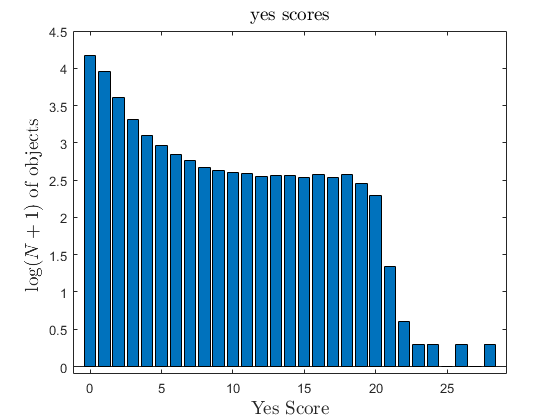



figure
hs=histcounts(objectTable.Ycls);%./ngal*100;
%histogram(objectTable.Ycls,29)

%xx=unique(objectTable.Ycls);
 bar(0:length(hs)-1,log10(hs+1));
% text(0:length(hs)-1,hs,num2str(hs','%0.2f'),'vert','bottom','horiz','center');
%box off
%ax=gca;
%ax.YAxis.Visible='off';
ylim([-0.1 4.5])
%set(gca,'ytick',[])
xlabelmine(' Yes Score');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('yes scores');

## enforce dates of project

We limit the classifications to the actual dates of the project: 1/6/21 to 14/6/21 

% set beginning and end dates 
beginDate=datetime('01/06/21 00:00','InputFormat',"dd/MM/yy HH:mm");
endDate=datetime('14/06/21 23:59','InputFormat',"dd/MM/yy HH:mm");

beforeMask=clsTab.created_at<beginDate;
projectMask=clsTab.created_at>=beginDate & clsTab.created_at<=endDate;
afterMask=clsTab.created_at>endDate;

% enforce mask on table
beforeTab=clsTab(beforeMask,:);
projectTab=clsTab(projectMask,:);
afterTab=clsTab(afterMask,:);

objBefore=jellyfish.readClassification.build_object_table(beforeTab);
objProject=jellyfish.readClassification.build_object_table(projectTab);
objAfter=jellyfish.readClassification.build_object_table(afterTab);



## plot classifications in epochs

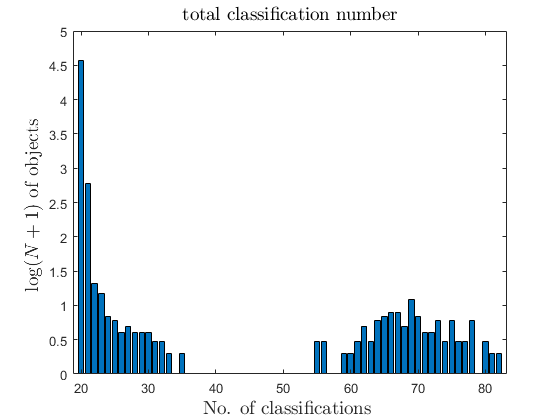

% project 
figure
xx=min(objProject.Ncls):max(objProject.Ncls);%  unique(objectTable.Ycls);
hs=histcounts(objProject.Ncls,length(xx));
bar(xx,log10(hs+1));

xlabelmine('No. of classifications ');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('total classification number');


fprintf('percentage of objects with more than 20 classifications: %s',num2str(sum(objProject.Ncls>20)./ngal.*100));

percentage of objects with more than 20 classifications: 1.9981

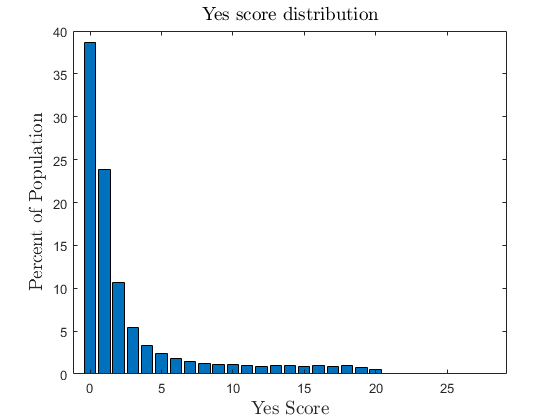



figure
hs=histcounts(objProject.Ycls)/ngal*100;

 bar(0:length(hs)-1,hs);

 xlabelmine(' Yes Score');
ylabelmine('Percent of Population');
titlemine('Yes score distribution');

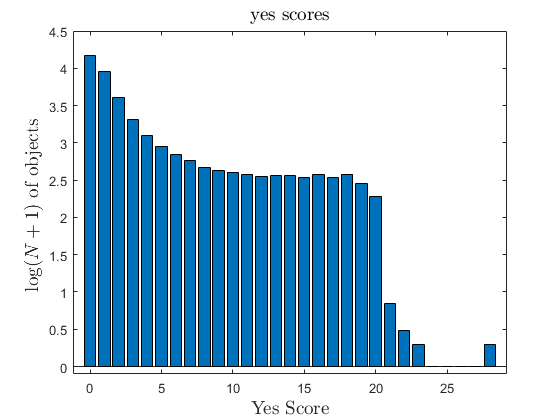


figure
hs=histcounts(objProject.Ycls);%./ngal*100;
 bar(0:length(hs)-1,log10(hs+1));
ylim([-0.1 4.5])
xlabelmine(' Yes Score');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('yes scores');

## before

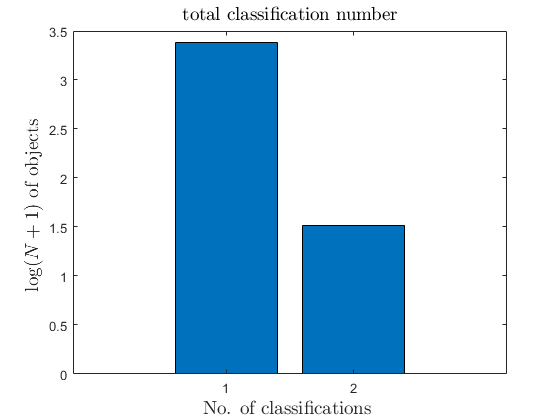



figure
xx=min(objBefore.Ncls):max(objBefore.Ncls);%  unique(objectTable.Ycls);
hs=histcounts(objBefore.Ncls,length(xx));
bar(xx,log10(hs+1));

xlabelmine('No. of classifications ');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('total classification number');


fprintf('percentage of objects with more than 20 classifications: %s',num2str(sum(objBefore.Ncls>20)./height(objBefore).*100));

percentage of objects with more than 20 classifications: 0

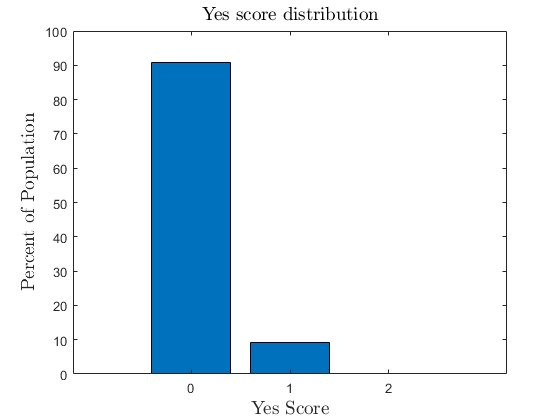



figure
hs=histcounts(objBefore.Ycls)/height(objBefore).*100;

 bar(0:length(hs)-1,hs);

xlabelmine(' Yes Score');
ylabelmine('Percent of Population');
titlemine('Yes score distribution');

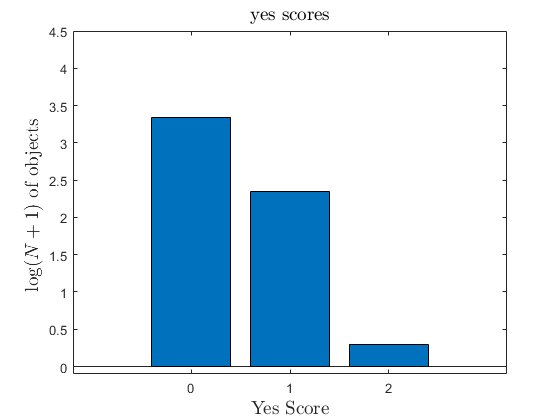


figure
hs=histcounts(objBefore.Ycls);%./ngal*100;
 bar(0:length(hs)-1,log10(hs+1));
ylim([-0.1 4.5])
xlabelmine(' Yes Score');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('yes scores');

## after

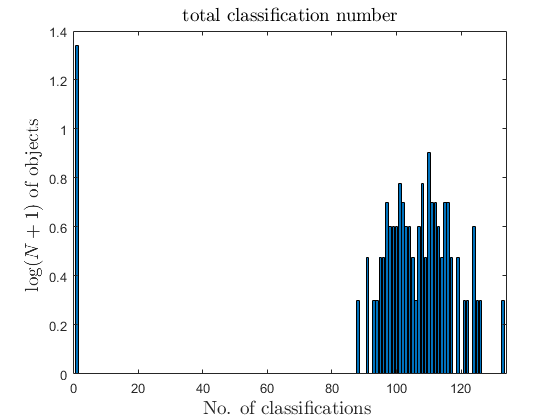



figure
xx=min(objAfter.Ncls):max(objAfter.Ncls);%  unique(objectTable.Ycls);
hs=histcounts(objAfter.Ncls,length(xx));
bar(xx,log10(hs+1));

xlabelmine('No. of classifications ');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('total classification number');


fprintf('percentage of objects with more than 20 classifications: %s',num2str(sum(objAfter.Ncls>20)./height(objBefore).*100));

percentage of objects with more than 20 classifications: 3.7007

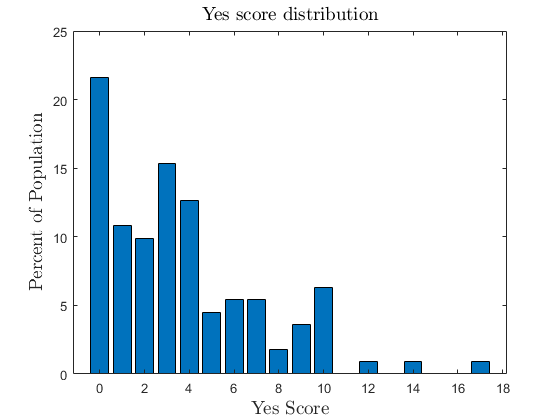



figure
hs=histcounts(objAfter.Ycls)/height(objAfter).*100;

 bar(0:length(hs)-1,hs);

 xlabelmine(' Yes Score');
ylabelmine('Percent of Population');
titlemine('Yes score distribution');

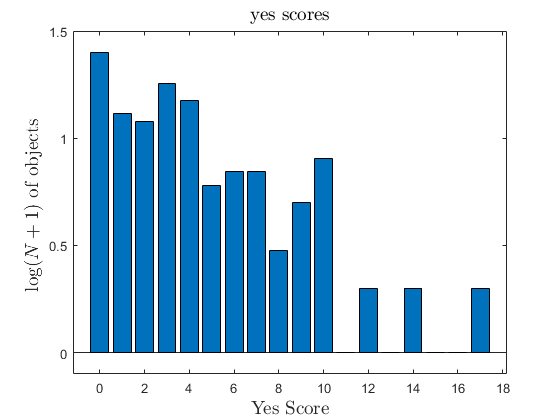


figure
hs=histcounts(objAfter.Ycls);%./ngal*100;
 bar(0:length(hs)-1,log10(hs+1));
ylim([-0.1 1.5])
xlabelmine(' Yes Score');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('yes scores');

## explore the objects with more than 20 votes

indList=find(objProject.Ncls>20); % indices of objects 
Nsample=200;
scores=zeros(length(indList),Nsample);
Ncls=zeros(length(indList),1);
YTcls=zeros(length(indList),1);

fprintf('number of objects with more than 20 classifications: %s',num2str(length(indList)));

number of objects with more than 20 classifications: 759


for i=1:length(indList)
    id=objProject.subject_ids(indList(i));
    
    cInds=find(projectTab.subject_ids==id);
    Ncls(i)=length(cInds);
    isJel=projectTab.isJelly(cInds);
    YTcls(i)=sum(isJel);
    
    for j=1:Nsample
        [~,ix]=sort(rand(1,Ncls(i)));
        scores(i,j)=sum(isJel(ix(1:20)));
        
    end
end
 

For each object with more than 20 classifications we subsample 20 out of the total classifications, and do that 200 times. We then find the maximal/minimal score over all subsamples and the average/median

## plot overflow objects

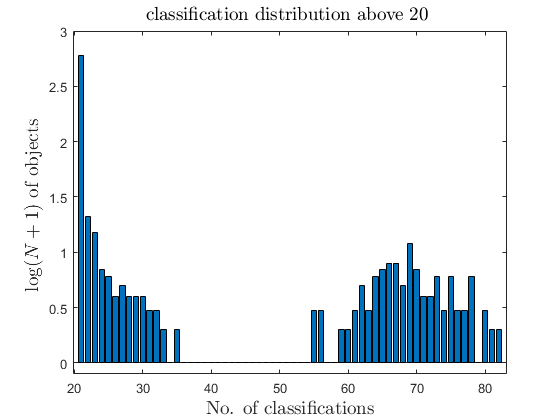

figure
xx=min(Ncls):max(Ncls);
hs=histcounts(Ncls,length(xx));%./ngal*100;
 bar(xx,log10(hs+1));
ylim([-0.1 3])

ylabelmine('$\log (N+1)$ of objects ');
xlabelmine('No. of classifications');
titlemine('classification distribution above 20 ');

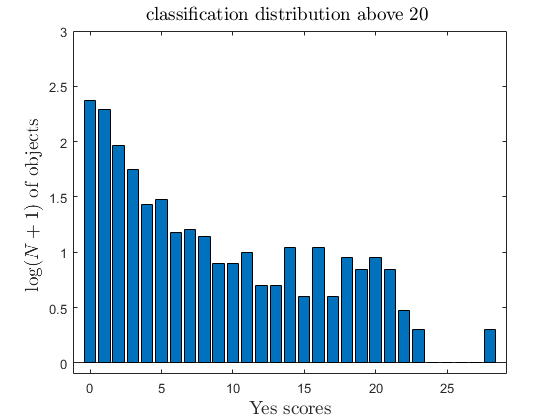


figure
xx=min(YTcls):max(YTcls);
hs=histcounts(YTcls,length(xx));%./ngal*100;
 bar(xx,log10(hs+1));
ylim([-0.1 3])

xlabelmine('Yes scores');
ylabelmine('$\log (N+1)$ of objects ');
titlemine('classification distribution above 20 ');

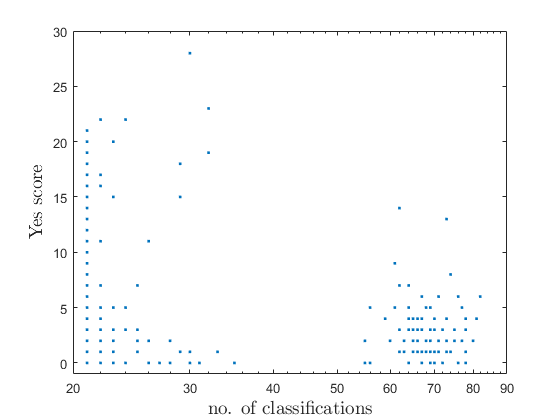



figure
semilogx(Ncls,YTcls,'.')
xlabelmine(' no. of classifications');
ylabelmine('Yes score');
xlim([20 90])
ylim([-1 30])

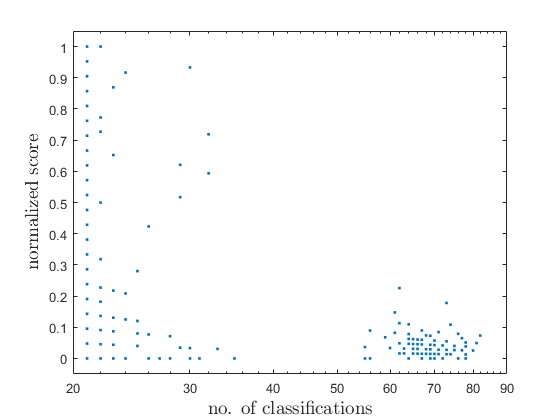


figure
semilogx(Ncls,YTcls./Ncls,'.')
xlabelmine(' no. of classifications');
ylabelmine('normalized score');
xlim([20 90])
ylim([-0.05 1.05])

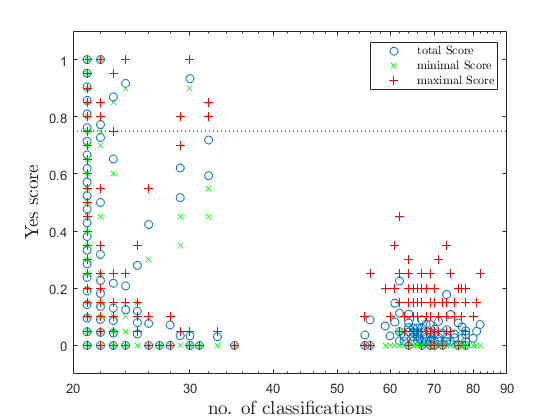


qus=quantile(scores,[0.25 0.75],2);
medScore=median(scores,2);
avgScore=mean(scores,2);
minScore=min(scores,[],2);
maxScore=max(scores,[],2);


figure
h=[];
xl=[20 90];
h(end+1)=semilogx(Ncls,YTcls./Ncls,'o','DisplayName','total Score');
hold on
h(end+1)=semilogx(Ncls,minScore./20,'xg','DisplayName','minimal Score');
h(end+1)=semilogx(Ncls,maxScore./20,'+r','DisplayName','maximal Score');
plot(xl,0.75.*ones(size(xl)),':k')
xlim(xl)
ylim([-0.1 1.1])
legend(h,'Interpreter','latex','location','best')
xlabelmine(' no. of classifications');
ylabelmine('Yes score');

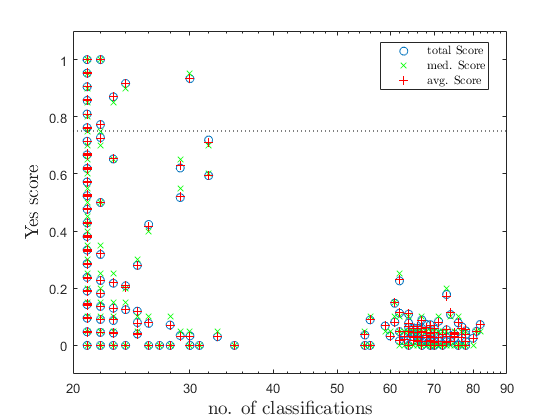


figure
h=[];
xl=[20 90];
h(end+1)=semilogx(Ncls,YTcls./Ncls,'o','DisplayName','total Score');
hold on
h(end+1)=semilogx(Ncls,medScore./20,'xg','DisplayName','med. Score');
h(end+1)=semilogx(Ncls,avgScore./20,'+r','DisplayName','avg. Score');
plot(xl,0.75.*ones(size(xl)),':k')
xlim(xl)
ylim([-0.1 1.1])
legend(h,'Interpreter','latex','location','best')
xlabelmine(' no. of classifications');
ylabelmine('Yes score');



fprintf('Number of objects with min<15 and max>=15 : %s',num2str(sum(minScore<15 & maxScore>=15)))

Number of objects with min<15 and max>=15 : 6

fprintf('Number of objects with medScore<15 and avgScore>=15 : %s',num2str(sum(medScore<15 & avgScore>=15)))

Number of objects with medScore<15 and avgScore>=15 : 0

fprintf('Number of objects with avgScore<15 and medScore>=15 : %s',num2str(sum(medScore>=15 & avgScore<15)))

Number of objects with avgScore<15 and medScore>=15 : 0

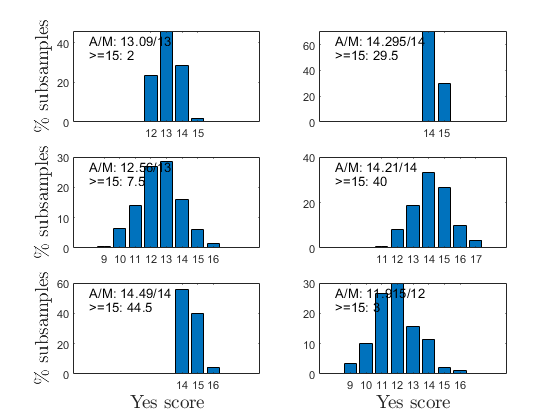


score6=scores(minScore<15 & maxScore>=15,:);

figure
for i=1:6
    scr=score6(i,:);
    xx=min(scr):max(scr);
    hs=histcounts(scr,length(xx))./Nsample*100;
    subplot(3,2,i)
    bar(xx,hs)
    xlim([7 19])
    yl=ylim;
   text(8,yl(1)+0.9*diff(yl),sprintf('A/M: %s/%s',num2str(mean(scr)),num2str(median(scr))));
   text(8,yl(1)+0.75*diff(yl),sprintf('>=15: %s' ,num2str(sum(scr>=15)./Nsample.*100)));
   
   if any(i==[5,6])
       xlabelmine('Yes score');
   end
   if any(i==[1 3 5])
       ylabelmine('\% subsamples');
   end
  
end





% 
% figure
% plot(Ncls,medScore,'x');
% hold on
% plot(Ncls,avg,'+')
%     %maxScore-minScore,'.')
% 
% 
% figure
% errorbar(1:length(indList),medScore,medScore-minScore,maxScore-medScore)
% 
% figure
% %plot(,minScore,'.')
% hold on
% plot(1:length(indList),maxScore,'.r')
% 
% figure
% plot(1:length(indList),diff(qus,1,2),'.')
% hold on 
% plot(1:length(indList),maxScore-minScore,'r.')
% %errorbar(1:10,med(1:10),abs(med(1:10)-qus(1:10,1)),abs(qus(1:10,2)-med(1:10)));
% 
% 
% %plot),./20,'+b');
% %hold on
% %plot(1:length(indList),YTcls./Ncls','xr');
% 
%     
% % figure
% % plot(1:10,med(1:10),1:10,qus(1:10,1))